# **Metodo Iterativo per la Risoluzione di un Sistema Lineare : Jacobi *****Analisi***

**Nella seguente documentazione mostriamo i test relativi all'accuratezza e alla robustezza del Metodo di Jacobi.**

# Test di Accuratezza

Il test di accuratezza determina quanto più è accurata la soluzione generata dall'algoritmo. Testando con parametri di ingresso tali che A è una matrice necessariamente sparsa di notevoli dimensioni, non singolare e ben condizionata, viene prodotto attraverso la funzione *CalcoloAccuratezza() *un grafico della sparsità della matrice in allegato *all'indice di condizionamento della matrice A, l'errore relativo, il residuo relativo e il numero di iterazioni.*

## **Esempio**

**Test con Matrice A tale che **$\rho \left(A\right)<1$. 

Il raggio spettrale della matrice è minore di 1, il test deve provare che l'algoritmo converge e propone il risultato corretto.

A = spdiags(rand(100,1),0,100,100);
x = ones(100,1);

Proviamo che il raggio spettrale è minore di 1

rho = max(eig(A))

rho = 0.9913

Verifica della funzione

Specificati tutti i parametri come uscita


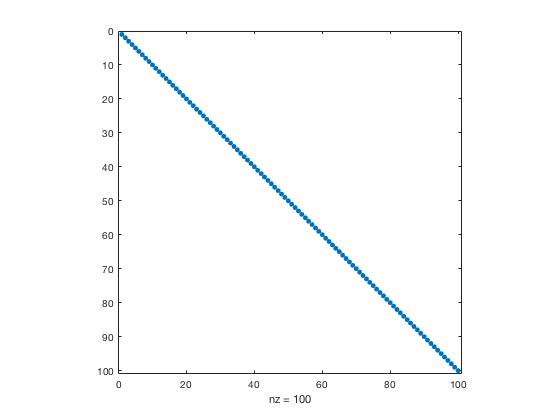

ans = struct with fields:
    indice_cond: 87.9822
     errore_rel: 0
        numiter: 2
      resid_rel: 0


CalcoloAccuratezza(A,x,eps,700)

**Test con Matrice A tale che **$\rho \left(A\right)=\|A\|$.

La matrice ha diagonale principale strettamente dominante. Questa è una condizione tale che l'algoritmo converge. Si verifica questa condizione con il risultato seguente.

Specificati tutti i parametri come uscita


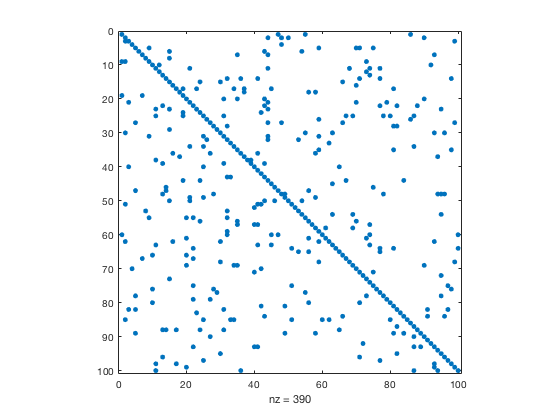

ans = struct with fields:
    indice_cond: 6.8805
     errore_rel: 1.7542e-14
        numiter: 46
      resid_rel: 1.1067e-14


A = sprand(100,100,0.03)+spdiags(ones(100,1),0,100,100)*3;
x = ones(100,1);
CalcoloAccuratezza(A,x,10^-13,900)

**Test con Matrice Sparsa '685_bus'**

Questa matrice è stata ricavata dal seguente indirizzo web:

[HB_685_bus](https://sparse.tamu.edu/HB/685_bus)

Dove nella quale essa descrive un problema di rete elettrica ottenuto in Russia nel Luglio del 1985. Il numero degli zeri indica le interruzioni di rete elettrica nei vari luoghi.

*N.B : Il parametro 'Problem' estrae una struttura dal file .mat caricato, per caricare la matrice A basta eseguire il comando A = Problem.A*

Specificati tutti i parametri come uscita


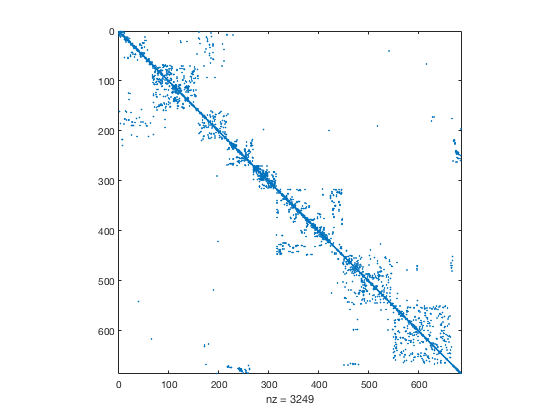

ans = struct with fields:
    indice_cond: 5.3104e+05
     errore_rel: 0.9200
        numiter: 800
      resid_rel: 7.0855e-05


load('685_bus.mat','Problem');
A = Problem.A;
x = ones(length(A),1);
CalcoloAccuratezza(A,x,eps,800)

**Test con matrice A tridiagonale**

Specificati tutti i parametri come uscita


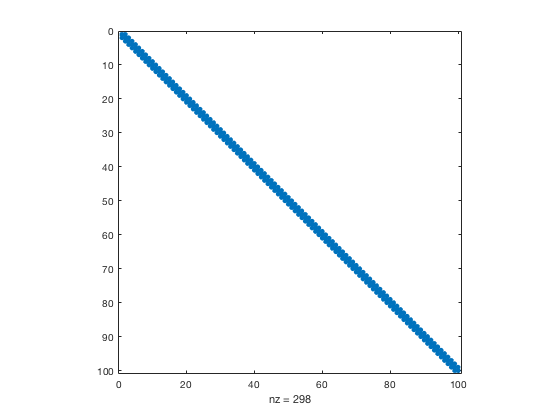

ans = struct with fields:
    indice_cond: 22.3333
     errore_rel: 2.2204e-16
        numiter: 358
      resid_rel: 2.1210e-16


A = gallery('tridiag',100,10,35,22);
x = ones(100,1);
CalcoloAccuratezza(A,x,eps,900)

**Test con Matrice A di Poisson**

Specificati tutti i parametri come uscita


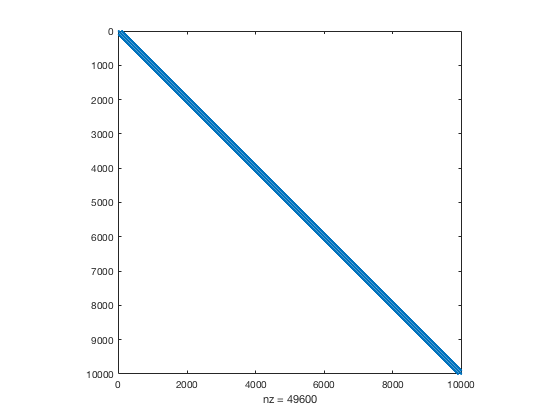

ans = struct with fields:
    indice_cond: 6.0107e+03
     errore_rel: 0.9076
        numiter: 1000
      resid_rel: 7.4052e-04


A = gallery('poisson',100);
x = ones(10000,1);
CalcoloAccuratezza(A,x,eps,1000)

**Esecuzione da interfaccia grafica**

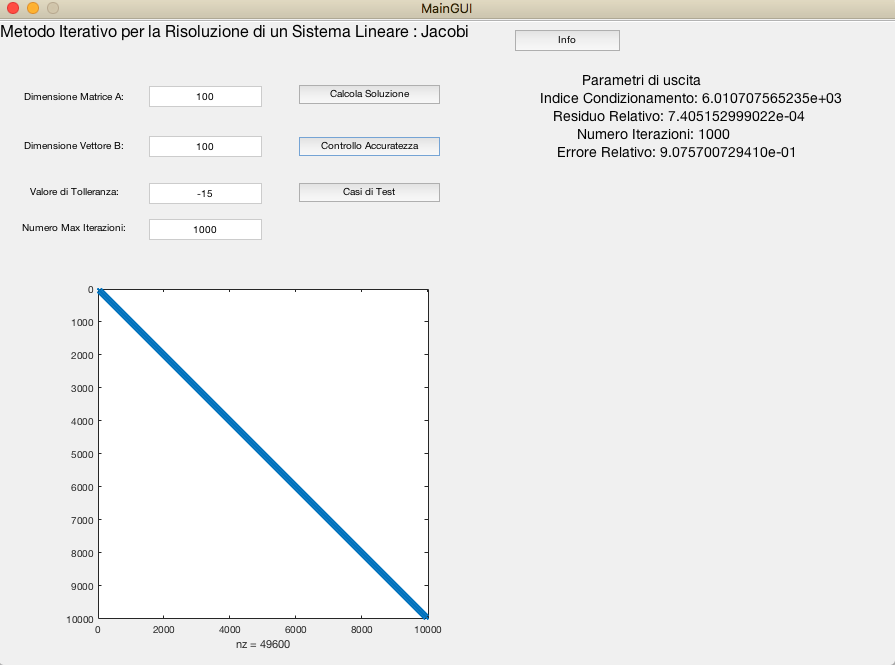

# Test di Robustezza

Per valutare la robustezza dell'algoritmo è stata implementata una test suite. I casi di test sono stati scelti a partire dalle condizioni di errore o warning che possono avere luogo. Ogni caso di test lo descriveremo brevemente a partire dai parametri di input e dalla funzionalità che  viene testata. Il numero di casi di test è: 15 ,implementati in una classe definita dal matlab *matlab.unittest.TestCase*. In tal modo si è automatizzato il processo di esecuzione dei test. Le istruzioni per eseguire i test saranno mostrate successivamente.

Di seguito seguono i casi di test più rilevanti che sono stati effettuati.

### **Test Case 1**

Verifica se la matrice immessa non è sparsa

**Input**

- A = rand(10);

- b = A*ones(10,1);

- TOL = 10^-8;

- MAXITER = 700;

### **Test Case 3**

Verifica se la matrice presenta uno zero sulla diagonale principale

**Input**

- A = sprand(10,10,0.1) + speye(10,10);

- A(1,1) = 0;

- b = A*ones(10,1);

- TOL = 10^-8;

- MAXITER = 700;

### Test Case 5

Verifica se il valore di tolleranza è negativo

- A = sprand(10,10,0.1) + speye(10,10);

- b = A*ones(10,1);

- TOL = -3;

- MAXITER = 10500;

### Test Case 8

Verifica se il numero massimo di iterazioni è negativo

- A = sprand(10,10,0.1) + speye(10,10);

- b = A*ones(10,1);

- TOL = 10^-8;

- MAXITER = -1;

### Test Case 9

Verifica se il vettore B non è un vettore

**Input**

- A = sprand(10,10,0.1) + speye(10,10);

- b = rand(10);

- TOL = 10^-8;

- MAXITER = 700;

### Test Case 11

Verifica se il numero massimo di iterazioni è molto grande

- A = sprand(10,10,0.1) + speye(10,10);

- b = A*ones(10,1);

- TOL = 10^-8;

- MAXITER = 10500;

### Test Case 13

Verifica se la tolleranza e il numero massimo di iterazioni non sono specificati

**Input**

- A = sprand(10,10,0.1) + speye(10,10);

- b = A*ones(10,1);

- TOL = non specificato

- MAXITER = non specificato

## Esecuzione Casi di Test

Il seguente codice esegue in modo automatizzato i casi di test implementati.

result = runtests('CasiTest.m')

Running CasiTest
.......... .....
Done CasiTest
__________



result =   1×15 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   15 Passed, 0 Failed, 0 Incomplete.
   0.21041 seconds testing time.


table(result)

ans = 15×6 table
            Name             Passed    Failed    Incomplete    Duration       Details   
    _____________________    ______    ______    __________    _________    ____________

    'CasiTest/TestCase1'     true      false       false        0.025504    [1×1 struct]
    'CasiTest/TestCase2'     true      false       false        0.010637    [1×1 struct]
    'CasiTest/TestCase3'     true      false       false       0.0065791    [1×1 struct]
    'CasiTest/TestCase4'     true      false       false        0.028465    [1×1 struct]
    'CasiTest/TestCase5'     true      false       false       0.0069527    [1×1 struct]
    'CasiTest/TestCase6'     true      false       false        0.013941    [1×1 struct]
    'CasiTest/TestCase7'     true      false       false        0.

## Riferimenti

- Testing in Matlab: [https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html](https://it.mathworks.com/help/matlab/matlab-unit-test-framework.html)

- [Docenti.unina.it D'alessio Alessandra](https://www.docenti.unina.it/#!/professor/414c455353414e4452414427414c455353494f444c534c534e3534433630463833394e/login)

- [Wikipedia : Metodo di Jacobi](https://it.wikipedia.org/wiki/Metodo_di_Jacobi)

## **Autori**

***Giuseppe Napolano M63000856 Raffaele Formisano M63000912 Giuseppe Romito M63000936***